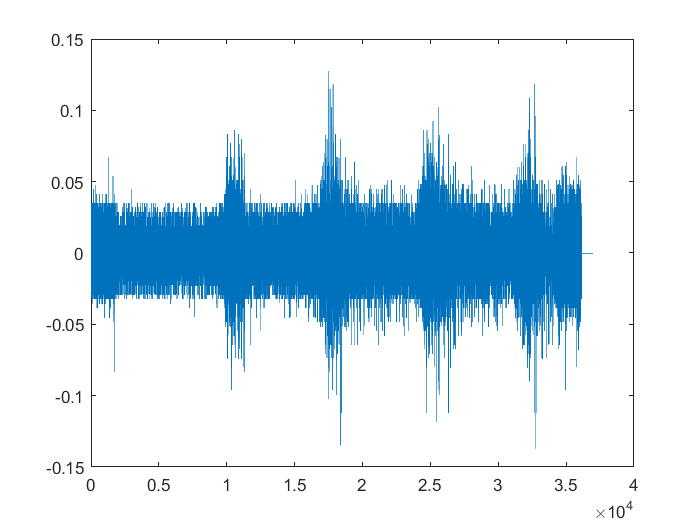

clear;
clc;

info= edfinfo('open_close.edf');
signal= edfread('open_close.edf', 'SelectedSignals','EMGBITREV');
data_carray= table2array(signal);
data= vertcat(data_carray{:});
figure
plot(data);

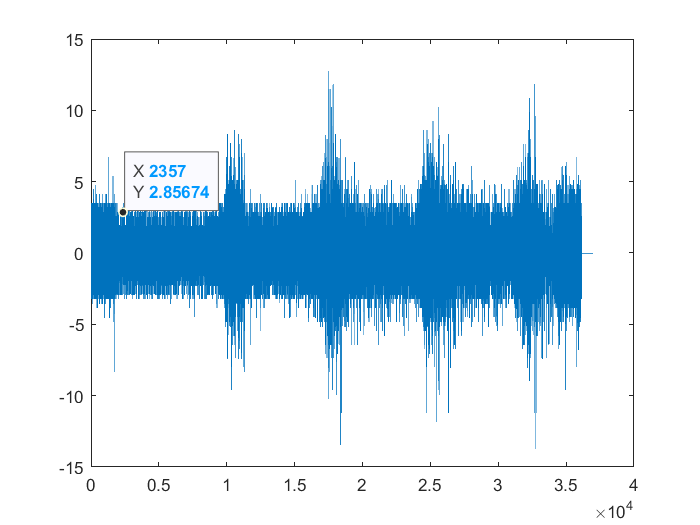


% y= fft(data);
% figure
% plot(y);

x_amp= data*100;

figure
plot(x_amp);


% x= data;
% mean= mean(x);
% variancia= var(x);
% desvio= std(x);
% 
% P_sinal= mean(x.^2);
% Pwn= mean(Wn.^2);
% SNR= P_sinal/Pwn;
% SNR_db= 10*log10(SNR);
% 
% SNR= 10^(SNRdB/10);
% sigma= sqrt(P_sinal/SNR);
% Wn= sigma*randn(size(sinal));
% new_sinal= round(sinal+ Wn);
% 
% figure
% plot(filtered_data);